Definimos la función que vamos a resolver, en este caso cambiamos el sistema, ya no es el de la clase 7, el sistema propuesto es similar, sin embargo ahora lo consideramos unicamente problema de condiciones iniciales


$$x\prime \prime (t) + 5 x \prime + 4x + 3y = e^{-6t} \sin(4t)$$
  


$$2y\prime + y + 4x\prime + 6x = e^{-6t} \cos(4t)$$


Con las siguientes condiciones iniciales, que son las siguientes:


$$x(0)=1, \;\;\;\; x\prime(0) = 2, \;\;\;\; y(0)=0$$


Las variables de estado seran 


$$x=x(1), \;\;\;\; x\prime=x(2), \;\;\;\; y=x(3)$$


f1=@(t,x)[x(2);...
          exp(-6*t)*sin(4*t)-5*x(2)-4*x(1)-3*x(3);...
          (1/2)*(exp(-6*t)*cos(4*t)-x(3)-4*x(2)-6*x(1))]

f1 = function_handle with value:
    @(t,x)[x(2);exp(-6*t)*sin(4*t)-5*x(2)-4*x(1)-3*x(3);(1/2)*(exp(-6*t)*cos(4*t)-x(3)-4*x(2)-6*x(1))]


Las condiciones iniciales que tenemos ahora son


$$x(0)=1, \;\;\;\; x\prime(0) = 2, \;\;\;\; y(0)=0$$


ci=[1; 2; 0];
rvt=linspace(1,4,2^7);

Resolvemos la ecucacion y graficamos

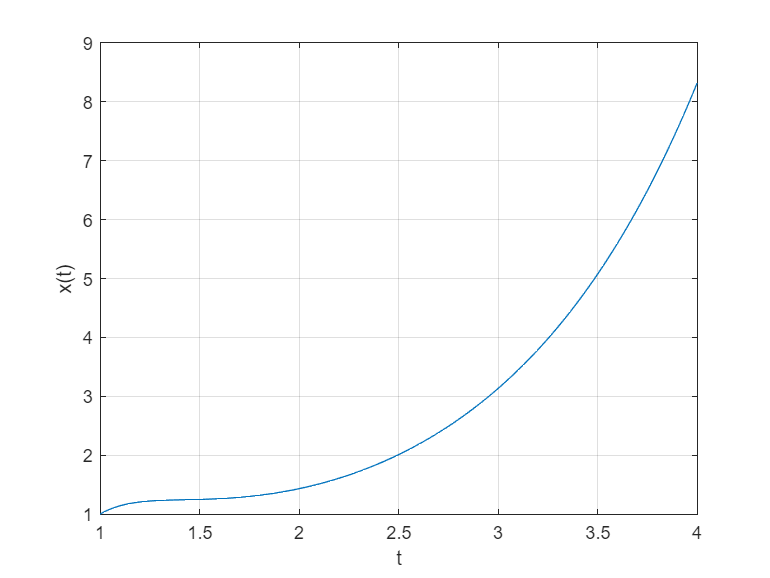

[t,x]=ode45(f1,rvt,ci);
plot(t,x(:,1)), grid, xlabel('t'),ylabel('x(t)')

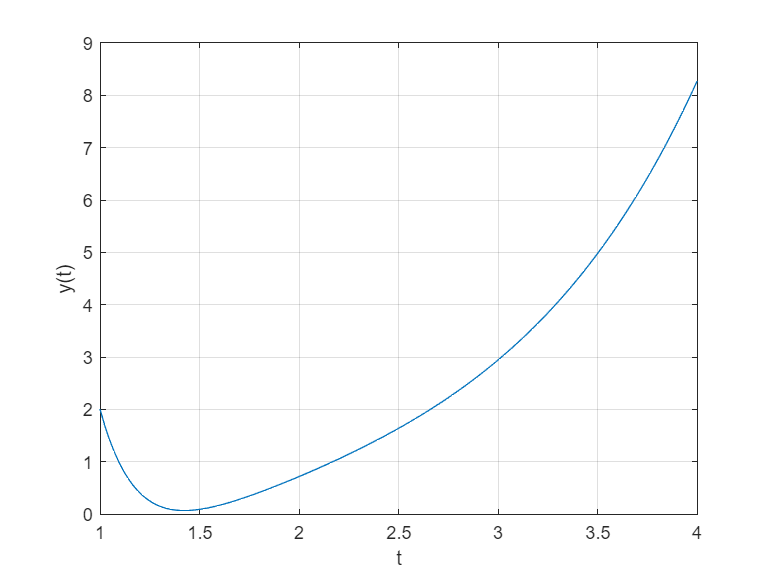

plot(t,x(:,2)), grid, xlabel('t'),ylabel('y(t)')

Haremos nuevamente otro ejemplo de ecucación difierencial

Resolveremos analiticamete la ecuación de Legendre y de Bessel, las cuales son respectimavamente


$$(1-t^2)\frac{d^2x(t)}{dx^2}-2t\frac{dx(t)}{dt}+n(n+1)x(t) = 0$$



$$t^2 \frac{d^2 x(t)}{dt^2}+t\frac{dx(t)}{dt}+(t^2-n^2)x(t)=0$$


Primero resolveremos la ecacucion de legrendre, activamos el toolbox simbolico e introducimos las variables

syms x(t) t n;
legendre=(1-t.^2)*diff(x,t,2)-2*t.*diff(x,t,1)+n.*(n+1)*x(t)==0

$$legendre(t) = -\left(t^{2}-1\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-2\,t\,\frac{\partial }{\partial t}x\left(t\right)+n\,x\left(t\right)\,\left(n+1\right)=0$$

Para resolver utilizamos el comando dsolve

sol_legendre(t)=dsolve(legendre)

$$sol\_legendre(t) = C_{1}\,{}_{2}F_{1}\left(\frac{n}{2}+\frac{1}{2},-\frac{n}{2};\frac{1}{2};t^{2}\right)+C_{2}\,t\,{}_{2}F_{1}\left(\frac{n}{2}+1,\frac{1}{2}-\frac{n}{2};\frac{3}{2};t^{2}\right)$$

Notamos que las soluciones son cuando menos "raras" para el lector no familiarizado, entonces mencionamos que la funcion F se define como una funcion Hipergeometrica. Donde


$$_i\,F_j(a_n,...\,,a_i;b_m, ...\,,b_j;k)$$
 

La "i" y la "j" representan el numero de indices de a y de b, para las soluciones de la ecuacion Legendre, tenemos i=2, j=1.

Para mas información sobre esta funcion. [Aqui](https://mathworld.wolfram.com/HypergeometricFunction.html)

Realizamos lo mismo ahora con la ecuación de Bessel

bessel_tarea=t.^2*diff(x,t,2)+t.*diff(x,t,1)+(t.^2-n^2)*x(t)==0

$$bessel\_tarea(t) = t^{2}\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+t\,\frac{\partial }{\partial t}x\left(t\right)-x\left(t\right)\,\left(n^{2}-t^{2}\right)=0$$

sol_bessel=dsolve(bessel_tarea)

$$sol\_bessel = C_{1}\,J_{n}\left(t\right)+C_{2}\,Y_{n}\left(t\right)$$

Mencionar que en eta solución, $J_n(t)$ y $Y_n(t)$ representa los polinomios de Bessel de primer y segundo orden respectivamente. Para mas información acerca de J [aqui](https://mathworld.wolfram.com/BesselFunctionoftheFirstKind.html) y de Y [aqui](https://mathworld.wolfram.com/BesselFunctionoftheSecondKind.html)